4. Use 2D Finite Differences to solve the following BVP

$u_{\textrm{xx}} +u_{\textrm{yy}} =0$,    $0<x<1$,$0<y<1$

subject to $u\left(x,y\right)=0$ on the top, left, and ride sides of the square domain with$u\left(x,y\right)=\sin \left(\pi x\right)$for$y=0$ (i.e.  the bottom of the square).  Use 5 grid points (3 interior points) in each of the x and y directions. Code up your FD method into Matlab and plot the solution. Does your FD solution improve with a finer grid? Is it possible to use too many points?  Discuss.  Think about how you could compute the 'true' analytic solution

For Finite Differences Method


$$\begin{array}{l}
\frac{1}{h^2 }\left(u_{i,j+1} -2u_{i,j} +u_{i,j-1} \right)+\frac{1}{h^2 }\left(u_{i+1,j} -2u_{i,j} +u_{i+1,j} \right)=0\\
\frac{1}{h^2 }\left(u_{i,j+1} -4u_{i,j} +u_{i,j-1} {+u}_{i+1,j} +u_{i+1,j} \right)=0\\
\frac{u_{i,j+1} }{h^2 }-\frac{4u_{i,j} }{h^2 }+\frac{u_{i,j-1} }{h^2 }+\frac{u_{i+1,j} }{h^2 }+\frac{u_{i+1,j} }{h^2 }=0\\
\frac{u_{i,j+1} }{h^2 }+\frac{u_{i,j-1} }{h^2 }+\frac{u_{i+1,j} }{h^2 }+\frac{u_{i+1,j} }{h^2 }-\frac{4u_{i,j} }{h^2 }=0\\
\frac{u_{i,j+1} }{h^2 }+\frac{u_{i,j-1} }{h^2 }+\frac{u_{i+1,j} }{h^2 }+\frac{u_{i+1,j} }{h^2 }-\frac{4}{h^2 }u_{i,j} =0\\
u_{i,j+1} +u_{i,j-1} +u_{i+1,j} +u_{i+1,j} ={4u}_{i,j} \\
\frac{1}{4}\left(u_{i,j+1} +u_{i,j-1} +u_{i+1,j} +u_{i+1,j} \right)=u_{i,j} 
\end{array}$$


$u_{i,j} =\frac{1}{4}\left(u_{i,j+1} +u_{i,j-1} +u_{i+1,j} +u_{i+1,j} \right)$ for each i,j in the interval points

So for 5 grid points (3 interior points) there will be 9 unknows 

The points are known if they are on the side.

Therefore we need to a 9 by 9 matrix to solve all of those 9 point.

Which is:

V*a=b

Where V is 9 by 9, a is vector contain 9 unknown interior point, and b is the known point from BC.

If we write up the equation for $i=2$ and $j=2$


$$\begin{array}{l}
u_{2,2} =\frac{1}{4}\left(u_{2,3} +u_{2,1} +u_{3,2} +u_{3,2} \right)\\
4u_{2,2} =u_{2,3} +u_{2,1} +u_{3,2} +u_{3,2} \\
4u_{2,2} -u_{2,3} -u_{2,1} -u_{3,2} -u_{3,2} =0
\end{array}$$


Since $u_{2,1}$is on the boundary


$$4u_{2,2} -u_{2,3} -u_{3,2} -u_{3,2} =u_{2,1}$$


If we arrange the unknown like:


$$a=\left\lbrack \begin{array}{c}
u_{2,2} \\
u_{2,3} \\
u_{2,4} \\
u_{3,2} \\
u_{3,3} \\
u_{3,4} \\
u_{4,2} \\
u_{4,3} \\
u_{4,4} 
\end{array}\right\rbrack$$


So the first row of V is 


$$\left\lbrack \begin{array}{ccccccccc}
4 & -1 & 0 & -1 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


The first element of b is $u_{2,1}$

And then if we write up for the second row


$$u_{2,3} =\frac{1}{4}\left(u_{2,4} +u_{2,2} +u_{3,3} +u_{3,3} \right)$$



$$4u_{2,3} -u_{2,4} -u_{2,2} -u_{3,3} -u_{3,3} =0$$


So the second row of V is 


$$\left\lbrack \begin{array}{ccccccccc}
-1 & 4 & -1 & 0 & -1 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


we could see the number 4 and -1 appears lots of times.

4 is the coeffecient on the point we need to know and -1 is the coeffecient on the point left, right, up and down of it the point on the BC will move to the correspounding element in b.

If we form the above in a matrix:


$$k=\left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
-1 & 4 & -1\\
0 & -1 & 0
\end{array}\right\rbrack$$


So we can keep load the matrix k into a all zero matrix and cut off the BC point then flat the matrix left to a row.

Which will become the row for matrix V.

The method I generate the matrix V, b and calculate result is:

grid point on x=$\textrm{nx}$

grid point on x=$\textrm{ny}$

set $k=\left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
-1 & 4 & -1\\
0 & -1 & 0
\end{array}\right\rbrack$

step 1: from the point$\left(2,2\right)$ to $\left(\textrm{nx}-1,\textrm{ny}-1\right)$:

    step 2: build up an all 0 matrix $M_z$ with dimension $\textrm{nx}$ by $\textrm{ny}$ (in this case is 5 by 5).

    change the point and all the point around it (in total 9 points) to matrix k.

    step 3: cut the matrix from $M_z \left(2,2\right)$ to $M_z \left(\textrm{nx}-1,\textrm{ny}-1\right)$

    step 4 flat the cut matrix to 1 row and restore is to the matrix V.

    step 5: for correspomding element in b, we could just add up all the point around it from the matrix of IC.

    (therefore only BC will be added since the other point is 0)

step 6: calculate a by V\b then reform a to$\left(\textrm{nx}-1\right)$by$\left(\textrm{ny}-1\right)$. Then put reformed a back into IC matrix.

By compute true solution

PDE                    $u_{\textrm{xx}} ={-u}_{\textrm{yy}}$                    $0<x<1$,    $0<y<1$

BCs                     $\left\lbrace \begin{array}{cc}
u\left(1,y\right)=0 & 0<y<1\\
u\left(x,1\right)=0 & 0<x<1
\end{array}\right.$

IC                        $\left\lbrace \begin{array}{cc}
u\left(0,y\right)=0 & \\
u\left(x,0\right)=\sin \left(\pi x\right) & 0\le x\le 1
\end{array}\right.$


$$u=X\left(x\right)Y\left(y\right)$$



$${X^{\prime } }^{\prime } \left(x\right)Y\left(y\right)=-X\left(x\right){Y^{\prime } }^{\prime } \left(y\right)$$



$$\frac{{X^{\prime } }^{\prime } \left(x\right)}{X\left(x\right)}=-\frac{{Y^{\prime } }^{\prime } \left(y\right)}{Y\left(y\right)}=k$$



$$\frac{{X^{\prime } }^{\prime } \left(x\right)}{X\left(x\right)}=k$$



$$\frac{{Y^{\prime } }^{\prime } \left(y\right)}{Y\left(y\right)}=-k$$


Case 1 $k>0$, $k=\lambda^2$,


$${X^{\prime } }^{\prime } \left(x\right)=\lambda^2 X\left(x\right)$$



$$X\left(x\right)=C_1 e^{\lambda x} +C_2 e^{-\lambda x}$$


IC                        $\left\lbrace \begin{array}{cc}
u\left(0,y\right)=0 & \\
u\left(x,0\right)=\sin \left(\pi x\right) & 0\le x\le 1
\end{array}\right.$


$$X\left(0\right)=C_1 e^{\lambda 0} +C_2 e^{-\lambda 0} =C_1 +C_2 =0$$



$$C_1 =-C_2$$


And by BCs

BCs                     $\left\lbrace \begin{array}{cc}
u\left(1,y\right)=0 & 0<y<1\\
u\left(x,1\right)=0 & 0<x<1
\end{array}\right.$


$$X\left(1\right)=C_1 e^{\lambda 1} +C_2 e^{-\lambda 1} ={-C}_2 e^{\lambda 1} +C_2 e^{-\lambda 1} =C_2 \left(e^{-\lambda } -e^{\lambda } \right)=0$$


So either $C_2 =0$ or$\left(e^{-\lambda } -e^{\lambda } \right)=0$

If $C_2 =0$,$C_1 =0$

Which $X\left(x\right)=0$ and then $u\left(x,y\right)=0$

So $C_2 =0$ is not true, $\left(e^{-\lambda } -e^{\lambda } \right)=0$

$e^{-\lambda } -e^{\lambda } =0$,


$$e^{-\lambda } =e^{\lambda }$$


The only$\lambda$that satisfies this equation is $\lambda =0$

Which means $X\left(x\right)=C_1 e^{0x} +C_2 e^{-0x}$

Which also means $X\left(x\right)=0$ and then $u\left(x,t\right)=0$

So $k>0$ is not true.

Case 2 $k=0$, $k=\lambda^2 =0$,so$\lambda =0$


$$X\left(x\right)=C_1 e^{\lambda x} +{\textrm{xC}}_2 e^{\lambda x} =C_1 +C_2 x$$


Plug in ICs

IC                        $\left\lbrace \begin{array}{cc}
u\left(0,y\right)=0 & \\
u\left(x,0\right)=\sin \left(\pi x\right) & 0\le x\le 1
\end{array}\right.$


$$X\left(0\right)=C_1 +C_2 0=C_1 =0$$


and BCs:

BCs                     $\left\lbrace \begin{array}{cc}
u\left(1,y\right)=0 & 0<y<1\\
u\left(x,1\right)=0 & 0<x<1
\end{array}\right.$


$$X\left(1\right)=C_1 +C_2 =C_2 =0$$


So$C_2 =0$

Therefor both $C_1$and $C_2$ equal to 0

$X\left(x\right)=0$for any situation and $u\left(x,t\right)=0$

So $k=0$ is not true.

Case 3 $k<0$, $k={-\lambda }^2$,$r_{1,2} =\pm \sqrt{-k}i=\pm \lambda i$

$a=0$,$b=\lambda$


$$X\left(x\right)=C_1 \cos \left(\lambda x\right)+C_2 \sin \left(\lambda x\right)$$


Plug in ICs

IC                        $\left\lbrace \begin{array}{cc}
u\left(0,y\right)=0 & \\
u\left(x,0\right)=\sin \left(\pi x\right) & 0\le x\le 1
\end{array}\right.$


$$X\left(0\right)=C_1 \cos \left(0\right)+C_2 \sin \left(0\right)=C_1 =0$$


and BCs:

BCs                     $\left\lbrace \begin{array}{cc}
u\left(1,y\right)=0 & 0<y<1\\
u\left(x,1\right)=0 & 0<x<1
\end{array}\right.$


$$X\left(1\right)=C_2 \sin \left(\lambda \right)=0$$



$$\lambda =n\pi$$



$$X\left(x\right)=C_n \sin \left(n\pi x\right)$$


Then for $Y\left(t\right)$,$-\frac{{Y^{\prime } }^{\prime } \left(y\right)}{Y\left(y\right)}=k$

for  $k<0$


$$Y\left(y\right)=a_n e^{\lambda y} +b_n e^{-\lambda y}$$


BCs                     $\left\lbrace \begin{array}{cc}
u\left(1,y\right)=0 & 0<y<1\\
u\left(x,1\right)=0 & 0<x<1
\end{array}\right.$


$$Y\left(1\right)=a_n e^{\lambda } +b_n e^{-\lambda } =0$$


So 


$$U\left(x,y\right)=X\left(x\right)Y\left(y\right)=\sum_1^{\infty } C_n \sin \left(n\pi x\right)\left\lbrack a_n e^{\lambda y} +b_n e^{-\lambda y} \right\rbrack$$


Let $C_n a_n =A_n$$C_n b_n =B_n$


$$u\left(x,y\right)=\sum_{n=1}^{\infty } \sin \left(n\pi x\right)\left\lbrack A_n e^{n\pi y} +B_n e^{-n\pi y} \right\rbrack$$


Then plug IC in:

IC                        $\left\lbrace \begin{array}{cc}
u\left(0,y\right)=0 & \\
u\left(x,0\right)=\sin \left(\pi x\right) & 0\le x\le 1
\end{array}\right.$


$$u\left(x,0\right)=\sum_{n=1}^{\infty } \sin \left(n\pi x\right)\left\lbrack A_n +B_n \right\rbrack =\sin \left(\pi x\right)$$


n only could be 1


$$\begin{array}{l}
A_n +B_n =1\\
A_n =1-B_n 
\end{array}$$


then from BCs

BCs                     $\left\lbrace \begin{array}{cc}
u\left(1,y\right)=0 & 0<y<1\\
u\left(x,1\right)=0 & 0<x<1
\end{array}\right.$


$$u\left(x,1\right)=\sum_{n=1}^{\infty } \sin \left(n\pi x\right)\left\lbrack A_n e^{n\pi } +B_n e^{-n\pi } \right\rbrack =0$$


since $\sin \left(n\pi x\right)$could not be 0


$$\begin{array}{l}
A_n e^{n\pi } +B_n e^{-n\pi } =0\\
{\left(1-B_n \right)e}^{n\pi } +B_n e^{-n\pi } =0\\
{e^{n\pi } -B_n e}^{n\pi } +B_n e^{-n\pi } =0\\
e^{n\pi } -B_n \left(e^{n\pi } +e^{-n\pi } \right)=0\\
e^{n\pi } =B_n \left(e^{n\pi } +e^{-n\pi } \right)\\
\frac{e^{n\pi } }{e^{n\pi } +e^{-n\pi } }=B_n \\
B_n =1-\frac{1}{e^{2n\pi } +1}
\end{array}$$


So $A_n =\frac{1}{e^{2n\pi } +1}$

since n only could be 1

$u\left(x,y\right)=\sin \left(\pi x\right)\left\lbrack \frac{1}{e^{2n\pi } +1}e^{\pi y} +\left(1-\frac{1}{e^{2n\pi } +1}\right)e^{-\pi y} \right\rbrack$        (10)

nx=5;%set grid point of x is 5
ny=5;%set grid point of y is 5

%general initial condition
x=linspace(0,1,nx);
y=linspace(0,1,ny);
u=zeros(nx,ny);
u(ny,:)=sin(pi*x);%set u(x,y)=sin(pi*x)

[uk]=FD(nx,ny,u)%calculate result

uk =          0    0.7071    1.0000    0.7071    0.0000
         0    0.3318    0.4693    0.3318         0
         0    0.1509    0.2134    0.1509         0
         0    0.0584    0.0825    0.0584         0
         0         0         0         0         0


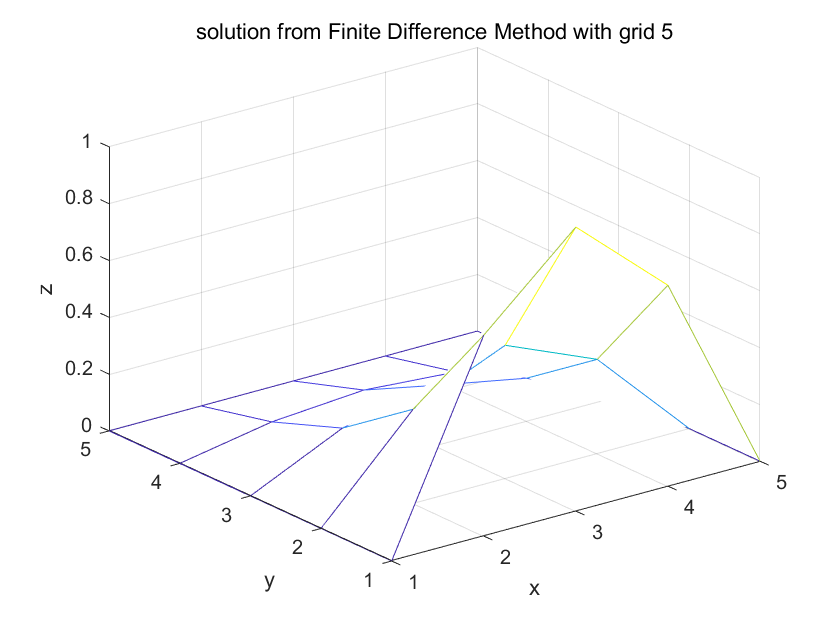


mesh(uk)
title("solution from Finite Difference Method with grid 5")
xlabel('x')
ylabel('y')
zlabel('z')


%test for more grid point
nx50=50;
ny50=50;

x50=linspace(0,1,nx50);
y50=linspace(0,1,ny50);
u50=zeros(nx50,ny50);
u50(ny50,:)=sin(pi*x50);

[uk50]=FD(nx50,ny50,u50)

uk50 =          0    0.0641    0.1279    0.1912    0.2537    0.3151    0.3753    0.4339    0.4907    0.5455    0.5981    0.6482    0.6957    0.7403    0.7818    0.8202    0.8551    0.8866    0.9144    0.9385    0.9587    0.9749    0.9872    0.9954    0.9995    0.9995    0.9954    0.9872    0.9749    0.9587    0.9385    0.9144    0.8866    0.8551    0.8202    0.7818    0.7403    0.6957    0.6482    0.5981    0.5455    0.4907    0.4339    0.3753    0.3151    0.2537    0.1912    0.1279    0.0641    0.0000
         0    0.0601    0.1199    0.1792    0.2378    0.2955    0.3519    0.4068    0.4601    0.5115    0.5608    0.6078    0.6523    0.6941    0.7331    0.7691    0.8018    0.8313    0.8574    0.8800    0.8989    0.9142    0.9257    0.9333    0.9372    0.9372    0.9333    0.9257    0.9142    0.8989    0.8800    0.8574    0.8313    0.8018    0.7691    0.7331    0.6941    0.6523    0.6078    0.5608    0.5115    0.4601    0.4068    0.3519    0.2955    0.2378    0.1792    0.1199    0.0601  

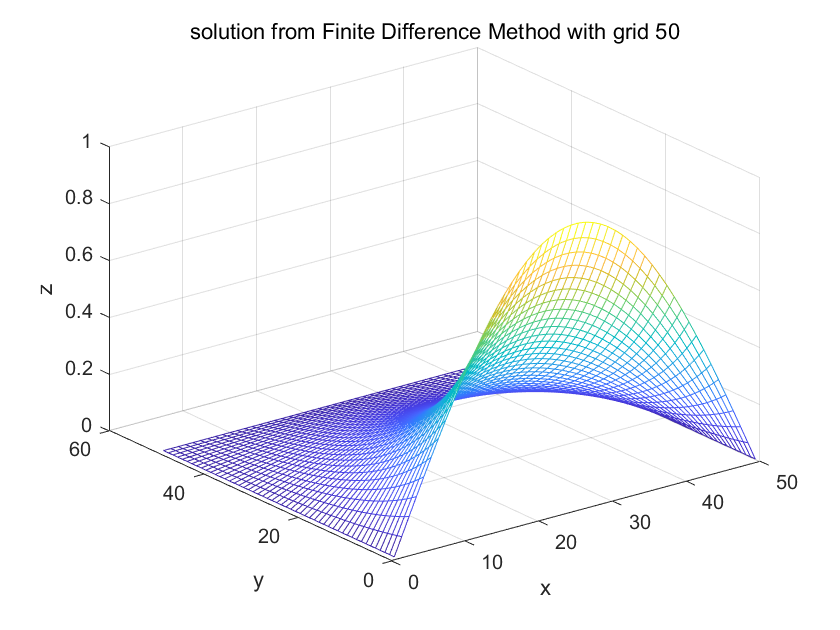


mesh(uk50)
title("solution from Finite Difference Method with grid 50")
xlabel('x')
ylabel('y')
zlabel('z')

From just looking at the graph we could see the graph with more grid is more smooth than it with less grid.

Now for testing the accuracy. We need to compute, the difference between the approximate value with the true value with different numbers of grid.

%true value for 5 grid point
[xx,yy]=meshgrid(x,y);
%equation (10)
tu=sin(pi*xx).*(1/(exp(2*pi)+1)*exp(pi.*yy)+(1-1/(exp(2*pi)+1))*exp(-pi.*yy))

tu =          0    0.7071    1.0000    0.7071    0.0000
         0    0.3247    0.4592    0.3247    0.0000
         0    0.1531    0.2165    0.1531    0.0000
         0    0.0808    0.1143    0.0808    0.0000
         0    0.0610    0.0863    0.0610    0.0000


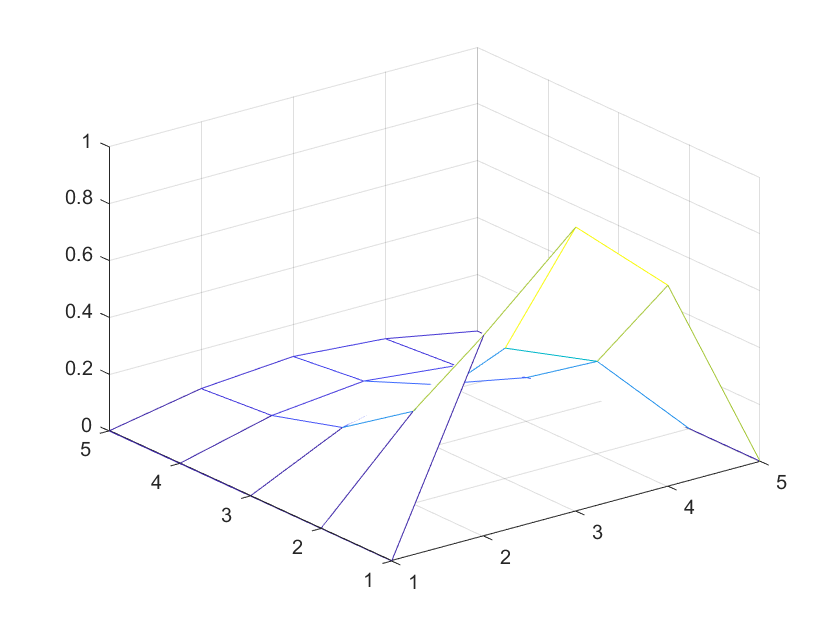

%plot the result
mesh(tu)

%calculate the average difference between true value and approximate value
Diff_grid_5 = sum(abs(tu-uk),'all')/((nx-1)*(ny-1))

Diff_grid_5 = 0.0198

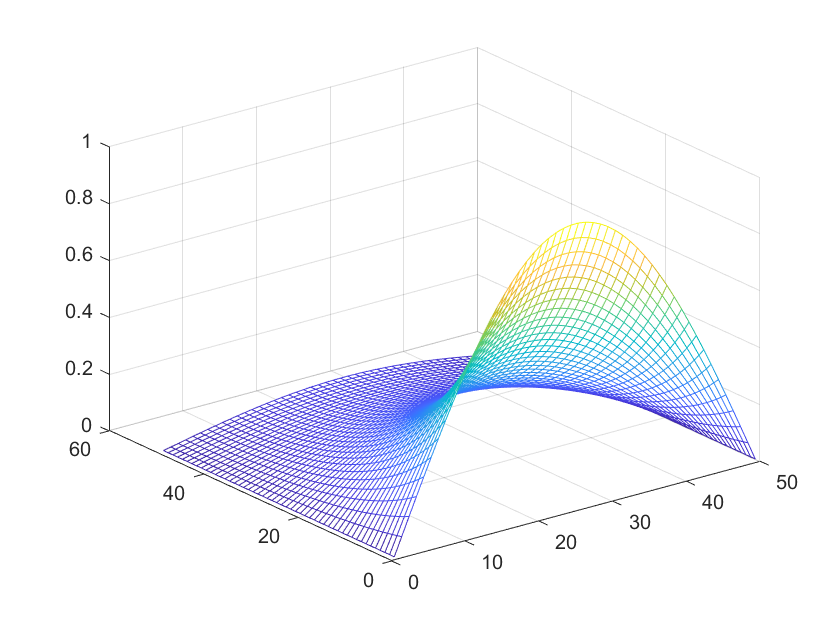


%true value for 50 grid point
[xx50,yy50]=meshgrid(x50,y50);
%equation (10)
tu50=sin(pi*xx50).*(1/(exp(2*pi)+1)*exp(pi.*yy50)+(1-1/(exp(2*pi)+1))*exp(-pi.*yy50));
%plot the result
mesh(tu50)

%calculate the average difference between true value and approximate value
Diff_grid_50 = sum(abs(tu50-uk50),'all')/((nx-1)*(ny-1))

Diff_grid_50 = 2.4831

So as result the more grid we have the less accuracy we will have.

function [uk] = FD(nx, ny, u)
%function of processing finite difference
%set k
    k = [0 -1 0;
        -1 4 -1;
        0 -1 0];
    V = [];
    b = [];
%step 1 loop from (2,2) to (nx-1),(ny-1)
    for j = 2:ny - 1
        for l = 2:nx - 1
            %step 2 set all 0 matrix 
            ut = zeros(ny, nx);
            %step 2 change the points around to k
            ut(j - 1:j + 1, l - 1:l + 1) = k;
            %step 3 cut the matrix from (2,2) to (nx-1),(ny-1)
            uc = ut(2:nx - 1, 2:ny - 1);
            %step 4 flat the cut matrix to 1 row and store it to V
            V = [V;reshape(uc', 1, (nx - 2)*(ny - 2))];
            %step 5 calculate b by adding the around point from IC matrix
            %together
            b = [b;u(j + 1, l) + u(j, l - 1) + u(j - 1, l) + u(j, l + 1)];
        end
    end
    uin = V\b;%step 6 calculate the result.
    u(2:nx - 1, 2:ny - 1) = reshape(uin, (nx - 2), (ny - 2))';
    %put the solution back into IC matrix.
    uk = flipud(u);
end

